%% Demo: multipole sources in the staggered 2D acoustic solver
clear
close all
clc

%% Grids and medium
domain = [0,1];
xPressure = Grid1DUnifPrimal(domain,161);
yPressure = Grid1DUnifPrimal(domain,161);
pressureGrid = GridSpace2D(xPressure,yPressure);

velocityXGrid = GridSpace2D( ...
    Grid1DUnifDual(xPressure),yPressure);
velocityYGrid = GridSpace2D( ...
    xPressure,Grid1DUnifDual(yPressure));

outputGrid = GridSpace2D( ...
    Grid1DUnifPrimal(domain,81), ...
    Grid1DUnifPrimal(domain,81));
medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);

%% Time grids
[~,~,~,~,cMax] = sampleMedium2D(pressureGrid,medium);
cflLimit = 6/7;
dt = 0.80*cflLimit/(cMax*sqrt(sum(1./pressureGrid.h.^2)));
times = 0:dt:0.9;
outputTimes = linspace(0,times(end),81);

%% Define two pressure multipoles
% An order-zero pressure monopole at (0.35,0.45).
monopole = MultipoleTerm2D( ...
    [0.35,0.45],[0,0], ...
    @(t) exp(-((t-0.10)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

% An x-derivative of delta at (0.65,0.55). The factor multiplying the
% dipole is proportional to the grid spacing so that its discrete strength
% is visually comparable with that of the monopole.
xDipole = MultipoleTerm2D( ...
    [0.65,0.55],[1,0], ...
    @(t) exp(-((t-0.18)/0.035).^2), ...
    Amplitude=pressureGrid.h(1),TargetField="pressure");

% Construct the multipole collection and discretize it on the three
% staggered computational grids.
multipole = MultipoleSource2D( ...
    [monopole,xDipole],ApproximationOrder=4);
source = multipole.discretize( ...
    pressureGrid,velocityXGrid,velocityYGrid);

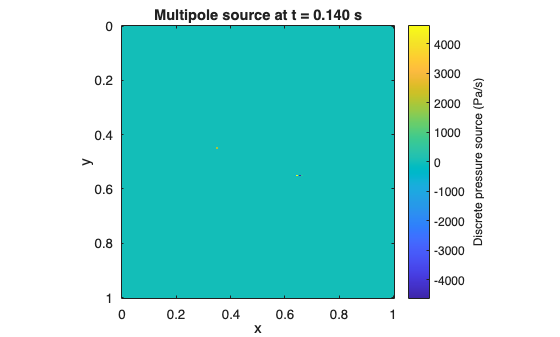

%% Inspect the time-weighted discrete source
% Evaluating the prepared source includes the term amplitudes and their
% temporal pulses. Both sources are partially active at this time.
inspectionTime = 0.14;
preparedSource = source.preparePressure(pressureGrid);
sourceValues = source.evaluatePrepared(preparedSource,inspectionTime);
sourceSnapshot = GridFunction(pressureGrid, ...
    Label="Discrete pressure source",Units="Pa/s");
sourceSnapshot.setValues(sourceValues);

ax = axes(figure(Name="Discrete 2D multipole source"));
sourceSnapshot.plot(Parent=ax);
axis(ax,'image');
title(ax,sprintf('Multipole source at t = %.3f s',inspectionTime));

%% Four-sided PML and solver
pml = PML2D( ...
    WidthLeft=0.15,WidthRight=0.15, ...
    WidthBottom=0.15,WidthTop=0.15, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

solver = AcousticSolver2D_PML( ...
    pressureGrid,times,outputGrid,outputTimes, ...
    medium,pml,SpatialOrder=4);

% Zero initial pressure and velocity
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

%% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

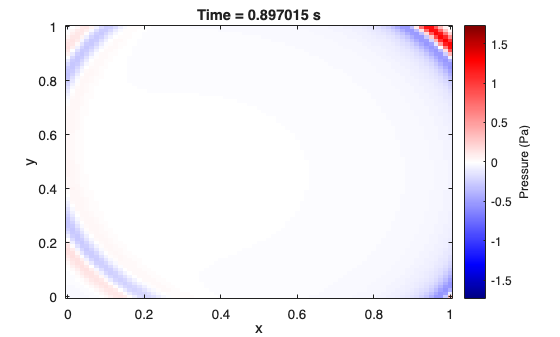

%% Animate pressure
ax = axes(figure(Name="Pressure generated by 2D multipoles"));
P.animate(Parent=ax,relLimFactor=0.1);

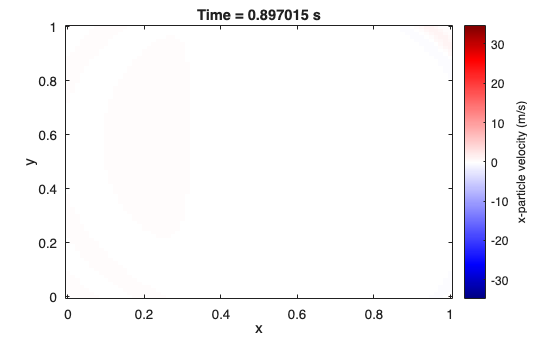

%% Optional velocity animations
ax = axes(figure(Name="x-velocity"));
Vx.animate(FramePause=0.03,Parent=ax);

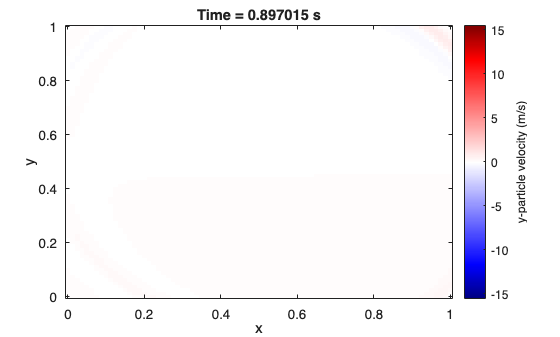


ax = axes(figure(Name="y-velocity"));
Vy.animate(FramePause=0.03,Parent=ax);